# **AER627 - Project 3 - Trajectory Generation**

## Kai Stewart - 501029849

clear;
clc;
close all;

%PHYSICAL PARAMS
L1 = 3*63.5; %mm
L2 = 2*63.5; %mm

%For ref. A4 paper is 210 x 297mm 
square_waypoints = [50, 50;
                    50, 150;
                    150, 150;
                    150, 50;
                    50, 50];

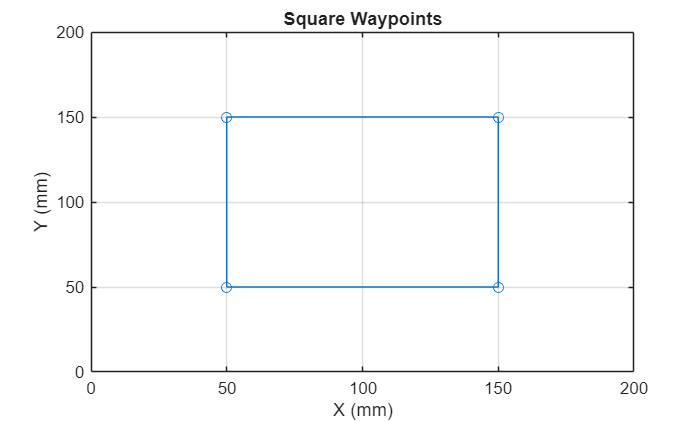

%WORKSPACE

%%plotting 
figure(1); 
square_waypoints_x = square_waypoints(:,1);
square_waypoints_y = square_waypoints(:,2);
plot(square_waypoints_x, square_waypoints_y, '-o')
grid on
xlabel('X (mm)')
ylabel('Y (mm)')
xlim([0 200]);
ylim([0 200]);
title('Square Waypoints')

%define a 2-link IK function that outputs 2 joint angles based on a waypoint (x,y) and the physical params
function [J1, J2] = inverse_kinematics(x, y, L1, L2) 
    cos_J2 = (x^2 + y^2 - L1^2 - L2^2) / (2 * L1 * L2); %     
    J2 = acos(max(-1, min(1, cos_J2))); 
    J1 = atan2(y, x - atan2(L2*sin(J2), L1 + L2*cos(J2))); 
end

% % Generate interpolated trajectory
% function joint_angles = generate_trajectory(waypoints, n_interp, l1, l2)
%     joint_angles = [];
%     for i = 1:size(waypoints, 1) - 1
%         x0 = waypoints(i, 1);   y0 = waypoints(i, 2);
%         x1 = waypoints(i+1, 1); y1 = waypoints(i+1, 2);
%         for t = linspace(0, 1, n_interp)
%             x = x0 + t*(x1 - x0);
%             y = y0 + t*(y1 - y0);
%             [q1, q2] = inverse_kinematics(x, y, l1, l2);
%             joint_angles = [joint_angles; rad2deg(q1), rad2deg(q2)];
%         end
%     end
% end

Export to SD Function 

% %export instructions out to SD card function 
% function export_to_sd(joint_angles, filename)
% 
%     %outputs to
%     T = array2table(joint_angles, 'VariableNames', {'j1_deg', 'j2_deg'});
%     writetable(T, filename);
%     fprintf('Successfully exported %d trajectory points to %s\n', size(joint_angles,1), filename);
% end